% PICK THE IMAGE TO USE TO PICK PTS FROM
% want full contrast, longest duration, frame 13-15 averaged
% and shown as image


% 1st step: PICK image TO CROP from DF

% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
colormap jet
imagesc(stdMap,[0 0.1])
title('stDev of dfof_bg across time(downsized)')


% DO the CROP

% crop manually by picking top left and then bottom right corners of a rectangle
[x y] = ginput(2);
df = df(y(1):y(2),x(1):x(2),:); % cropping df to be area I select 


% SHOW the CROPPED image

stdMap = std(df(:,:,1:10:end),[],3); 
figure
colormap jet
imagesc(stdMap,[0 0.1])
title('CROPped stDev of dfof_bg across time(downsized)') % axes are pixels?

% SHOW 2 REFERENCE IMAGE s
% topox & topoy maps w/overlay
% these variables are saved out in 'doTopography_KC as 
% 'topoXYwOverlay'

% how did we crop our onsetDf frames? Let's use the same crop size for topox map image
% we want our reference image cropped the same way as our activation image
topoXwOverlay = topoXYwOverlay{1};
topoYwOverlay = topoXYwOverlay{2};

topoXwOverlayCROP = topoXwOverlay(y(1):y(2),x(1):x(2),:);

Undefined function 'y' for input arguments of type 'double'.


topoYwOverlayCROP = topoYwOverlay(y(1):y(2),x(1):x(2),:)

df = df(y(1):y(2),x(1):x(2),:); 


% show topox topoy crop
figure
subplot(1,2,1);
imshow(topoXwOverlayCROP);
subplot(1,2,2);
imshow(topoYwOverlayCROP);
title('topox_& topoy crop w/overlay');


% PICKING ACTIVATION IMAGE
% image of highest contrast & duration during peak response

% pick trials based on desired contrast & durations      
c7d5trials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(7) & conAndDurOrderedByTrial(2,:) == uniqueDurations(5);

% pick frame range
clear frames
frames = [13:1:15]; 

% get selected frames from onsetDf 
clear onsetDfeachFrame
clear f

for f = 1:length(frames)
    onsetDfeachFrame(:,:,f,:) = onsetDf(:,:,frames(f),c7d5trials); 
end 

% take the average of the image across frames
clear meanOnsetDfeachFrame
meanOnsetDfeachFrame = squeeze(mean(onsetDfeachFrame,3));
meanOnsetDfeachFrame = mean(meanOnsetDfeachFrame,3);

% plot the mean peak activation image at highest stim parameters
range = [0 0.04];

range =          0    0.0400


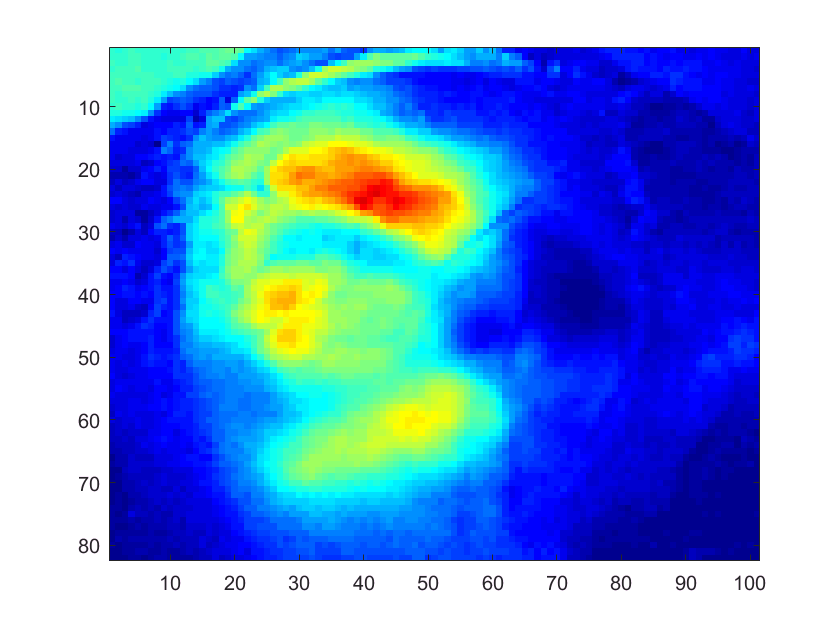

imagesc(meanOnsetDfeachFrame,range)


% just plot xpts ypts on un cropped df movie
